%import the error data that will allow for a good starting point for the membership funcitons
concentric = readmatrix('C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Front Concentric Error.txt');
eccentric = readmatrix('C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Front Eccentric Error.txt');

% Compute means and standard deviations
con_mean = mean(concentric, 2);
con_std = std(concentric, 0, 2);
ecc_mean = mean(eccentric, 2);
ecc_std = std(eccentric, 0, 2);

%Extract only the mean and standard deviation of the 2nd feature (knee
%separation). Then average the concentric and eccentric.
mu = rad2deg(mean([con_mean(1), ecc_mean(1)]))

mu = -0.0026

sigma = rad2deg(mean([con_std(1), ecc_std(1)]))

sigma = 3.6968

x1 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Torso\\Data.txt");
y1 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Torso\\Labels.txt");
x2 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Torso\\Data Corr.txt");
y2 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Torso\\Labels Corr.txt");

%concatenate the data and labels
X = cat(1, x1, x2);
Y = cat(1, y1, y2);

%reshape X and Y to be one dimensional
X1d = X(:);
Y1d = Y(:);

%Shuffle
perm = randperm(numel(X1d));
Xtrain = X1d(perm)

Xtrain =    21.3526
   18.3643
   26.8655
   -1.4950
   -0.5044
   16.1013
   -3.8847
   -0.8244
    0.3559
  -28.0325


Ytrain = Y1d(perm)

Ytrain =     1.0000
    1.0000
    1.0000
         0
         0
    0.5000
         0
         0
         0
   -0.5000



% Define tuning options
options = tunefisOptions(...
    "Method", "patternsearch", ...
    "OptimizationType", "tuning");

% Configure patternsearch parameters
options.MethodOptions = optimoptions('patternsearch', ...
    'MaxIterations', 30, ...
    'InitialMeshSize', 0.01, ...
    'MeshTolerance', 1e-3, ...
    'PollMethod', 'GPSPositiveBasis2N');

%create a cell array to store fis instances
fis1_instances = cell(1, 3);

%loop to create each optimised fis
for i = 1:3
    %create an instance of FIS1
    fis = FIS1Troso(sigma, mu, sprintf('fis1%d',i));

    %obtain only the input membership functions for tuning
    [in, ~, ~] = getTunableSettings(fis);

    %Exclude tuning of the "correct" MF (this was already chosen with data).
    % in(1).MembershipFunctions(1).Parameters.Free = [0 0];

    % Choose the optimisation parameters
    options.MethodOptions.MaxIterations = 200;        % Limited iterations
    options.MethodOptions.InitialMeshSize = 0.8;     % Small step size
    options.MethodOptions.MeshTolerance = 1e-4;      % Moderate precision
    % options.MethodOptions.PollMethod = 'GPSPositiveBasis2N'; % Reliable polling

    %tune the system
    fis1_tuned = tunefis(fis, in, Xtrain, Ytrain, options);

    %add the system to the instance array
    fis1_instances{i} = fis1_tuned;
end

patternsearch stopped because the mesh size was less than options.MeshTolerance.
patternsearch stopped because the mesh size was less than options.MeshTolerance.
patternsearch stopped because the mesh size was less than options.MeshTolerance.



fis11 = fis1_instances{1};
fis12 = fis1_instances{2};
fis13 = fis1_instances{3};

fis11.Inputs(1).MembershipFunctions

ans =   1×3 fismf array with properties:

    Type
    Parameters
    Name

  Details:
            Name          Type          Parameters    
         ___________    _________    _________________

    1    "Correct"      "gaussmf"    2.6218    -3.5526
    2    "Large_neg"    "sigmf"        -0.1     -41.55
    3    "Large_pos"    "sigmf"         0.1     52.325


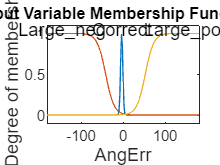

figure;
plotmf(fis11, 'input', 1);  % Change 1 to the index of the input you want to plot
title('Input Variable Membership Functions');

% fuzzyLogicDesigner(fis11);

%create the next layer
fis21 = FIS2('fis21');
fis22 = FIS2('fis22');

%create connections
con1 = ["fis11/Output" "fis21/A"];
con2 = ["fis12/Output" "fis21/B"];
con3 = ["fis21/C" "fis22/A"];
con4 = ["fis13/Output" "fis22/B"];

%create tree
fisT = fistree([fis11 fis12 fis13 fis21 fis22],[con1;con2;con3;con4]);

% Get tunable parameters (inputs, outputs, rules)
[in, out, rule] = getTunableSettings(fisT);

% Just tune the MF's of FIS21 and FIS22
for i = 1:numel(in)
    % Get the FIS name associated with the input MF
    fisName = in(i).FISName; % Access the FIS name
    
    % Freeze MF's for all FIS except fis21 and fis22
    if ~(strcmp(fisName, "fis22") || strcmp(fisName, "fis21"))
        % Loop through each membership function in the input
        for j = 1:numel(in(i).MembershipFunctions)
            in(i).MembershipFunctions(j).Parameters.Free = [0, 0]; % Freeze MF parameters
        end
    else
        %for fis21 and fis22 only allow the standard deviation to change
        for j = 1:numel(in(i).MembershipFunctions)
            in(i).MembershipFunctions(j).Parameters.Free = [1, 0];
        end
    end
end

% Reshape the data and labels
x_new = cat(1,x1,x2);
y_resh = cat(1,y1, y2);

% Find the index of the element with the largest magnitude in each row of y_resh
[~, ind] = max(abs(y_resh), [], 2);

% Extract the actual elements (not their absolute values) corresponding to these indices
y_new = y_resh(sub2ind(size(y_resh), (1:size(y_resh, 1))', ind));
y_new

y_new =    -0.5000
   -0.5000
   -9.0000
   -1.0000
    0.5000
    0.5000
    1.0000
    1.0000
   -0.5000
   -0.5000



%shuffle
perm_new = randperm(size(x_new, 1));
Xtrain_new = x_new(perm_new, :)

Xtrain_new =     0.3559   -0.5249    0.1725
   -3.1081   -2.8845   -1.5301
   -5.3242   -1.9423   -0.8574
  -18.5169  -22.9069  -28.3032
   10.1312   15.3433   19.3542
  -24.7943  -26.1579  -20.4845
   -0.8244   -3.8847    1.5128
    6.7781   13.8745   15.9728
   27.8936   21.3526   29.5329
   -2.5536   -0.8258    0.7413


Ytrain_new = y_new(perm_new)

Ytrain_new =          0
         0
         0
   -1.0000
    0.5000
   -0.5000
         0
    0.5000
    1.0000
         0


%now set up the tuning options.
options = tunefisOptions(...
    "Method", "patternsearch", ...
    "OptimizationType", "tuning");

% Configure patternsearch parameters
options.MethodOptions = optimoptions('patternsearch', ...
    'MaxIterations', 30, ...
    'InitialMeshSize', 0.5, ...
    'MeshTolerance', 1e-4, ...
    'PollMethod', 'GPSPositiveBasis2N');

%tune the rules
fisTree = tunefis(fisT, in, x_new, y_new, options)

patternsearch stopped because it exceeded options.MaxIterations.


fisTree =   fistree with properties:

                       Name: "fistreemodel"
                        FIS: [1×5 mamfis]
                Connections: [4×2 string]
                     Inputs: [3×1 string]
                    Outputs: "fis22/C"
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


u = getFISCodeGenerationData(fis11)

u = struct with fields:
            name: 'fis11'
            type: 'mamdani'
       andMethod: 'min'
        orMethod: 'max'
    defuzzMethod: 'centroid'
       impMethod: 'min'
       aggMethod: 'max'
           input: [1×1 struct]
          output: [1×1 struct]
            rule: [1×3 struct]


u1 = getFISCodeGenerationData(fis21)

u1 = struct with fields:
            name: 'fis21'
            type: 'mamdani'
       andMethod: 'min'
        orMethod: 'max'
    defuzzMethod: 'centroid'
       impMethod: 'min'
       aggMethod: 'max'
           input: [1×2 struct]
          output: [1×1 struct]
            rule: [1×25 struct]


u2 = getFISCodeGenerationData(fis22)

u2 = struct with fields:
            name: 'fis22'
            type: 'mamdani'
       andMethod: 'min'
        orMethod: 'max'
    defuzzMethod: 'centroid'
       impMethod: 'min'
       aggMethod: 'max'
           input: [1×2 struct]
          output: [1×1 struct]
            rule: [1×25 struct]


save("C:\Users\Cian\OneDrive\Documents\Imperial\Year 4\FYP\Trained MATLAB FIS\torso_f.mat", "u", "u1", "u2")

evalfis(fis11,0)

ans = -0.0267

evalFis([0.514167794, 12.512111, -10.51725777], fisT)

ans = 'Correct, well done! (Score: 0.11)'

% fuzzyLogicDesigner(fis22);

function res = evalFis(data, FIS)
    result = evalfis(FIS, data);

    if result < -0.6
        res = sprintf('Incorrect: Feet too close (Score: %.2f)', result);
    elseif result >= -0.6 && result < -0.2
        res = sprintf('Partially Incorrect: Feet too close (Score: %.2f)', result);
    elseif result >= -0.2 && result < 0.2
        res = sprintf('Correct, well done! (Score: %.2f)', result);
    elseif result >= 0.2 && result < 0.6
        res = sprintf('Partially Incorrect: Feet too far apart (Score: %.2f)', result);
    else
        res = sprintf('Incorrect: Feet too far apart (Score: %.2f)', result);
    end
end